clc;
clear;
close all;

 Data for the pre-defined curve (Original Shape)

load PlanarPoses.mat
Pose = PlanarPoses(3); % Only pose 3 is considered for this study
Pose.sDC=scaledDCs(Pose.DC,Pose.SegmentLengths);
%Bezier cubic interpolation
Segment1_TC_0 = Pose.TrueCoord(4,1:2);
Segment1_TC_1 = Pose.TrueCoord(5,1:2);
Segment1_DC_0 = Pose.sDC(4,1:2); %May need to scale them based on length
Segment1_DC_1 = Pose.sDC(5,1:2);%May need to scale them based on length

Plot

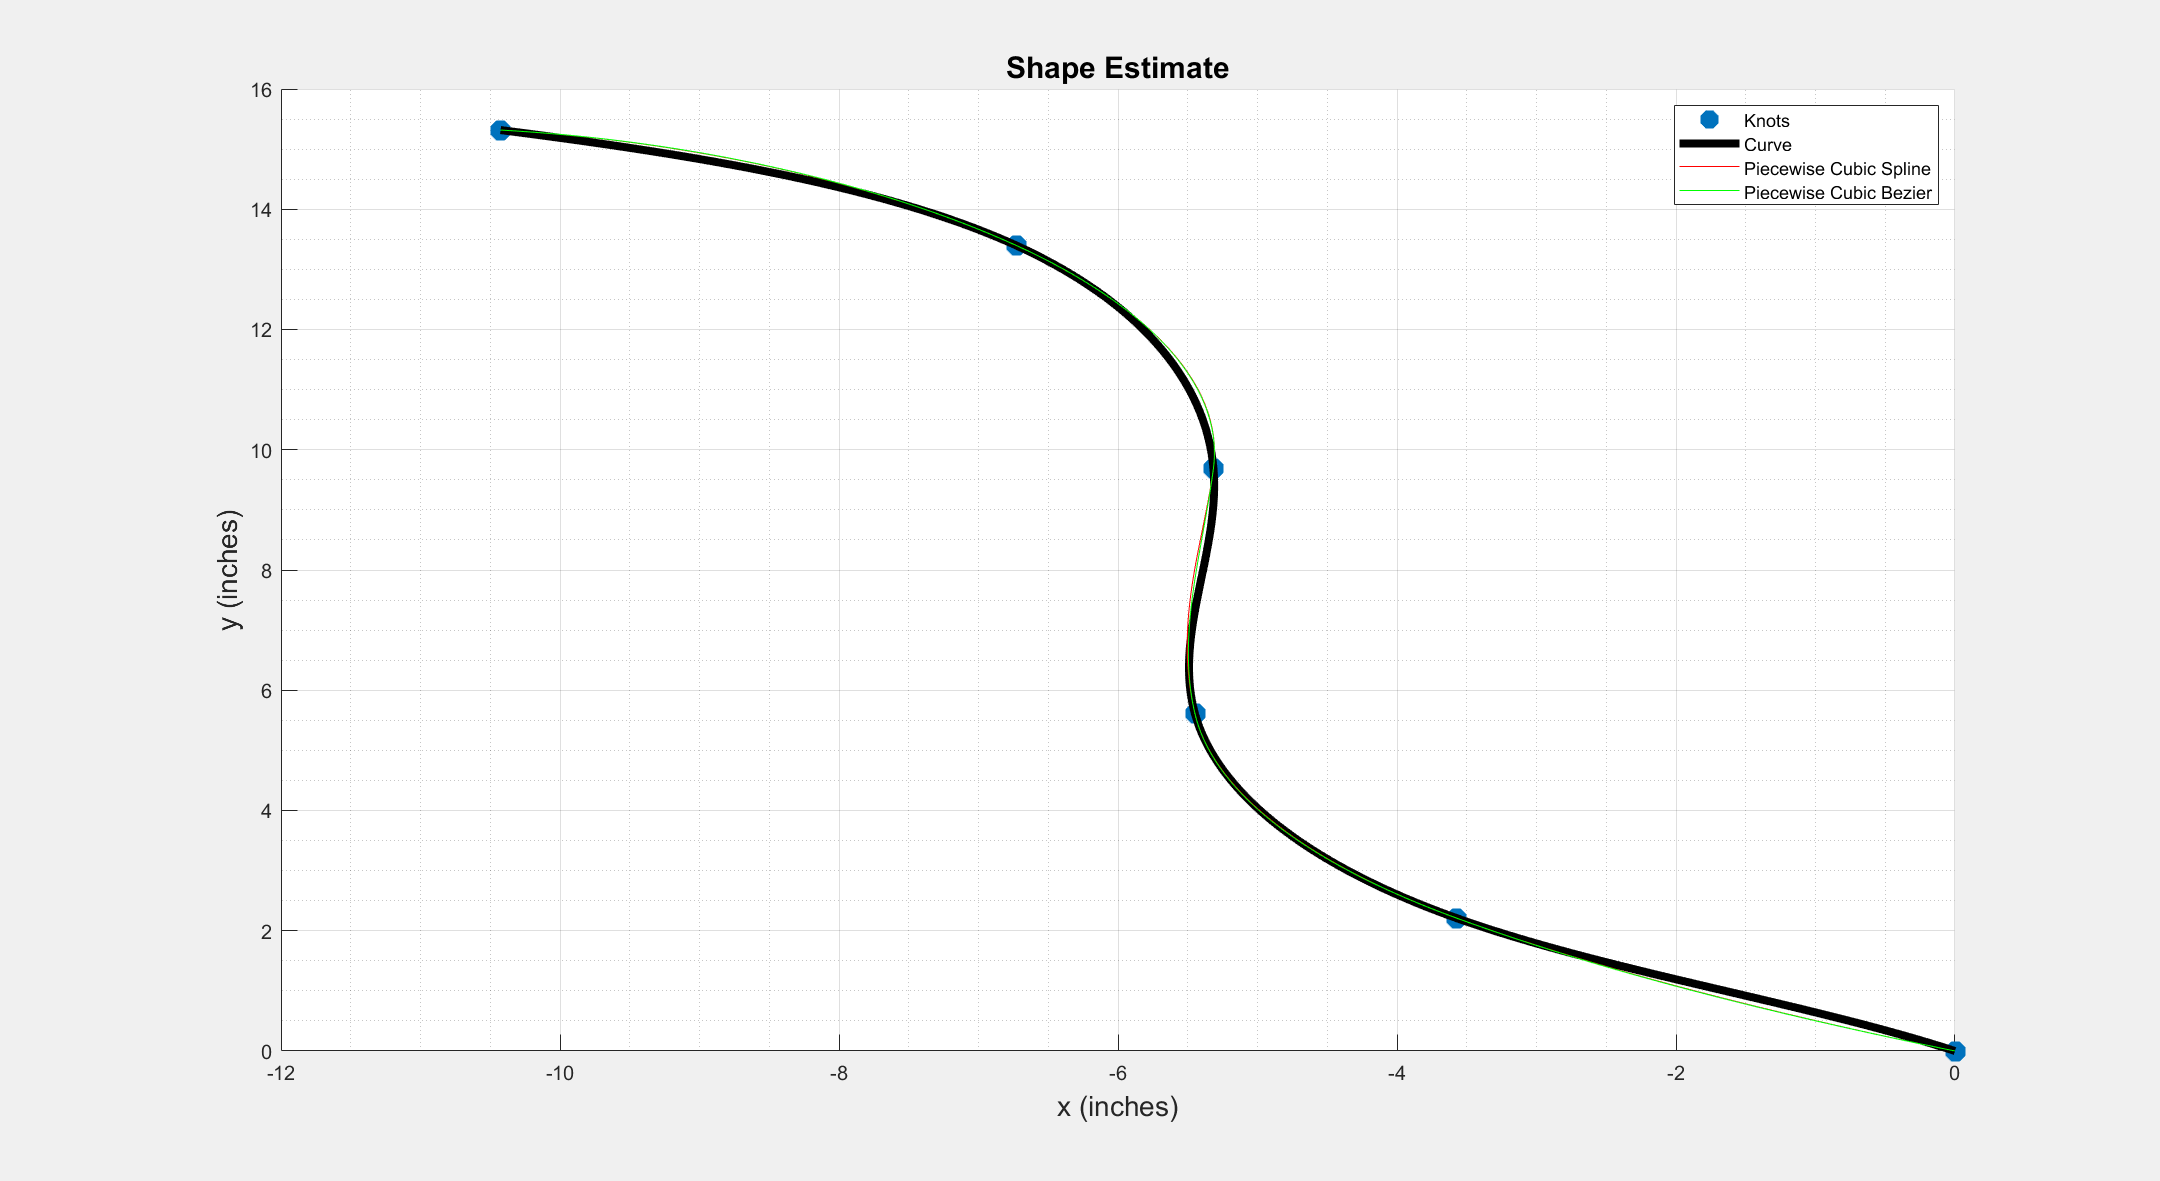

fig = openfig("toPlotOn.fig");
set(fig,"WindowState","maximized")
set(fig,'Visible','on')
set(gcf,'toolbar','fig')
set(gcf,'menubar','fig')
hold on
grid on
grid minor
%fig = figure('Name','Quintic Spline',"WindowState","maximized");
%set(fig,'Visible','on')

[X, Y] = CubicSpline(Segment1_TC_0, Segment1_TC_1, Segment1_DC_0, Segment1_DC_1);
%plot(X,Y, '--r','DisplayName','Cubic Spline')

[H_x, H_y] = cubicBezier(Segment1_TC_0, Segment1_TC_1, Segment1_DC_0, Segment1_DC_1);
%plot(H_x,H_y, '-b', 'DisplayName','Cubic Bezier')

[PCS_x, PCS_y] = PiecewiseCubicSpline(Pose.TrueCoord(:,1:2), Pose.sDC(:,1:2));
plot(PCS_x, PCS_y, '-r', 'DisplayName','Piecewise Cubic Spline')

[PCH_x, PCH_y] = PiecewiseCubicBezier(Pose.TrueCoord(:,1:2), Pose.sDC(:,1:2));
plot(PCH_x, PCH_y, '-g', 'DisplayName','Piecewise Cubic Bezier')

function n = scaledDCs(d,l)
    n = nan(size(d));
    n(1,:) = d(1,:)*l(1);
    n(end,:) = d(end,:)*l(end);
    for i = 2:length(d)-1
        n(i,:) = d(i,:)*(0.5*(l(i-1)+l(i)));
    end
end

Cubic Spline

function [X, Y] = CubicSpline(TC_0, TC_1, DC_0, DC_1)
    syms t a_x b_x c_x d_x
    f_x = a_x*t^4+b_x*t^2+c_x*t+d_x;
    df_x = diff(f_x,t);
    
    syms t a_y b_y c_y d_y
    f_y = a_y*t^4+b_y*t^2+c_y*t+d_y;
    df_y = diff(f_y,t);
    
    %Solve equations
    eq1 = subs(f_x,t,0) == TC_0(1);
    eq2 = subs(f_y,t,0) == TC_0(2);
    eq3 = subs(f_x,t,1) == TC_1(1);
    eq4 = subs(f_y,t,1) == TC_1(2);
    
    eq5 = subs(df_x,t,0) == DC_0(1);
    eq6 = subs(df_y,t,0) == DC_0(2);
    eq7 = subs(df_x,t,1) == DC_1(1);
    eq8 = subs(df_y,t,1) == DC_1(2);
    
    [A,B] = equationsToMatrix([eq1,eq2,eq3,eq4,eq5,eq6,eq7,eq8],[a_x,b_x,c_x,d_x,a_y,b_y,c_y,d_y]);
    AB = vpa(linsolve(A,B),2);
    
    % Substitute
    syms a_x b_x c_x d_x a_y b_y c_y d_y
    sf_x(t) = subs(f_x, [a_x b_x c_x d_x], AB(1:4)');
    sf_y(t) = subs(f_y, [a_y b_y c_y d_y], AB(5:8)');
    T = 0:0.01:1;
    X = double(subs(sf_x,t,T));
    Y = double(subs(sf_y,t,T));
end

**Piecewise Cubic Spline**

function [X, Y] = PiecewiseCubicSpline(P, DC)
    % P and DC takes only planar coordinates
    n = length(P)-1; % no. of segments
    for i=1:n
        if i == 1
            [X,Y] = CubicSpline(P(i,:),P(i+1,:), DC(i,:),DC(i+1,:));
            X_e = X(end);
            Y_e = Y(end);
        else
            [X_i, Y_i] = CubicSpline(P(i,:),P(i+1,:), DC(i,:),DC(i+1,:));
            X = [X, X_i]; Y = [Y, Y_i];
            %X_n = X_e+X_i;
            %Y_n = Y_e+Y_i;
            %X = [X, X_n];
            %Y = [Y, Y_n];
            %X_e = X(end);
            %Y_e = Y(end);
        end
    end
end

**Cubic Bezier**

function [X,Y] = cubicBezier(P0,Pf,d0,df)
    syms t a_x b_x c_x d_x
    B_x = (1-t)^3*a_x+(1-t)^2*t*b_x+(1-t)*t^2*c_x+t^3*d_x;
    dB_x = diff(B_x, t);
    eq1 = subs(B_x,t,0) == P0(1);
    eq2 = subs(B_x,t,1) == Pf(1);
    eq3 = subs(dB_x,t,0) == d0(1);
    eq4 = subs(dB_x,t,1) == df(1);
   
    syms t a_y b_y c_y d_y
    B_y = (1-t)^3*a_y+(1-t)^2*t*b_y+(1-t)*t^2*c_y+t^3*d_y;
    dB_y = diff(B_y, t);
    eq5 = subs(B_y,t,0) == P0(2);
    eq6 = subs(B_y,t,1) == Pf(2);
    eq7 = subs(dB_y,t,0) == d0(2);
    eq8 = subs(dB_y,t,1) == df(2);
    
    [A,B] = equationsToMatrix([eq1,eq2,eq3,eq4,eq5,eq6,eq7,eq8],[a_x,b_x,c_x,d_x,a_y,b_y,c_y,d_y]);
    AB = vpa(linsolve(A,B),2);
    
    syms a_x b_x c_x d_x a_y b_y c_y d_y
    sf_x(t) = subs(B_x, [a_x b_x c_x d_x], AB(1:4)');
    sf_y(t) = subs(B_y, [a_y b_y c_y d_y], AB(5:8)');
    T = 0:0.01:1;
    X = subs(sf_x,t,T);
    Y = subs(sf_y,t,T); 
end

**PieceWise Cubic Bezier (B-Splines)**

%Integrate this simpler in to the other functions - later
function [X, Y] = PiecewiseCubicBezier(P, DC)
    % P and DC takes only planar coordinates
    n = length(P)-1; % no. of segments
    for i=1:n
        if i == 1
            [X,Y] = cubicBezier(P(i,:),P(i+1,:), DC(i,:),DC(i+1,:));
        else
            [X_i, Y_i] = cubicBezier(P(i,:),P(i+1,:), DC(i,:),DC(i+1,:));
            X = [X, X_i]; Y = [Y, Y_i];
        end
    end
end